clear all
close all
clc

m = ones(1,5);
m(1)=100; m(2)=300; m(3)=600; m(4)=1500; m(5)=5000;
n(1)=5; n(2)=10; n(3)=15; n(4)=40; n(5)=90;
P = 1:3:35;
[Pr, Pc] = size(P);
speedup = ones(Pr, Pc ,5,5);



for k=1:5

    for z=1:5
    
        for i=1:size(P,2)
        
            K = sqrt(m(z)/2);
            time_old = m(z) * (3*n(k)*K + K + n(k) + 1) + n(k)*K;
            time_new = m(z)/P(i) * (3*n(k)*K + K + n(k) + 1) + K * (2*P(i) + n(k));
            speedup(1,i,z,k) = time_old / time_new;
        
        end
    
    end

end


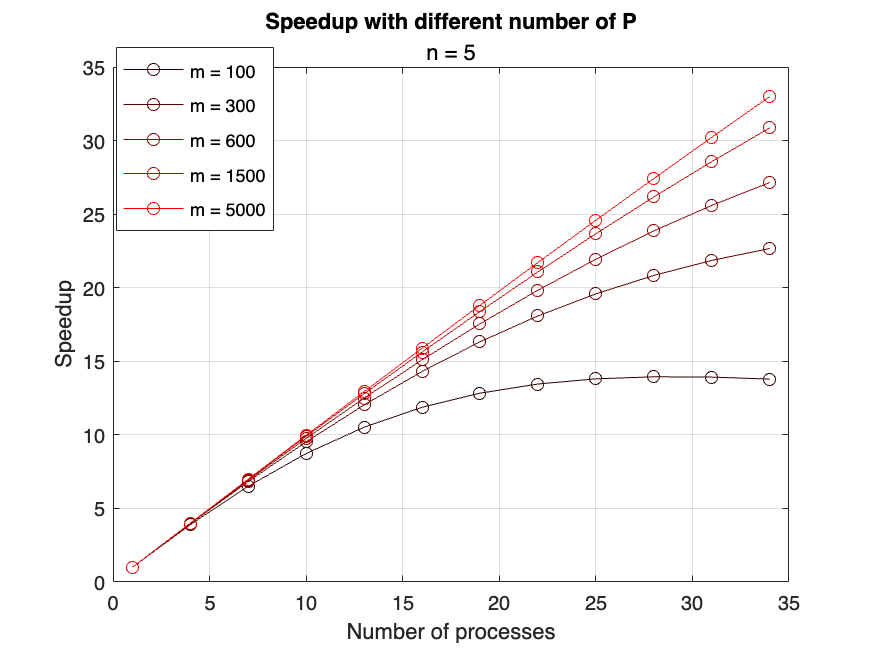

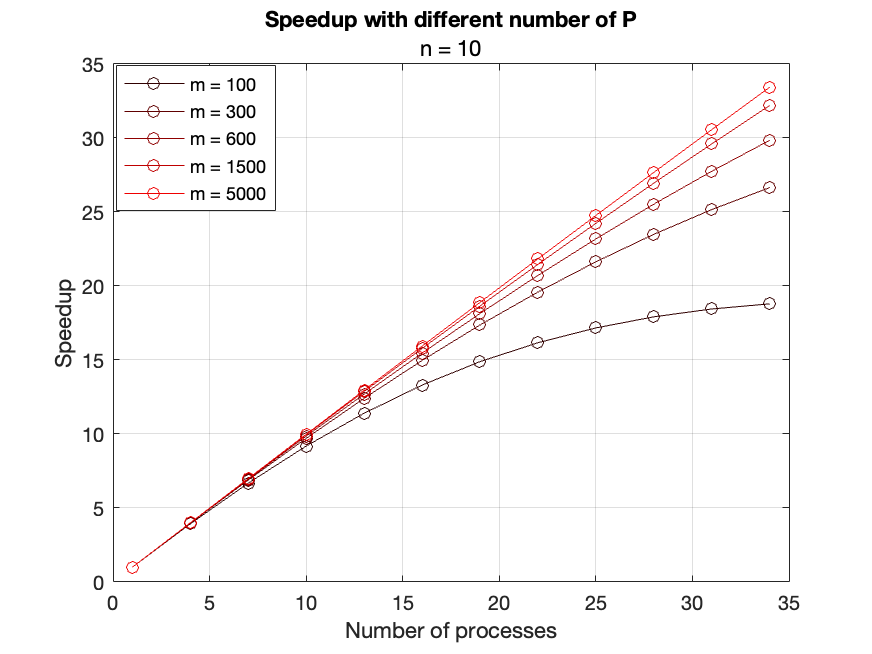

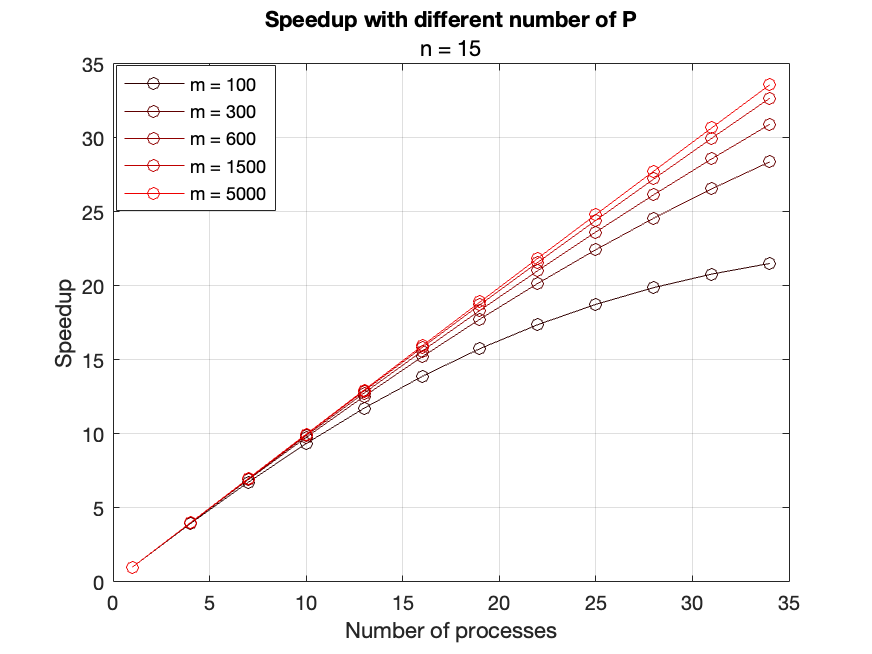

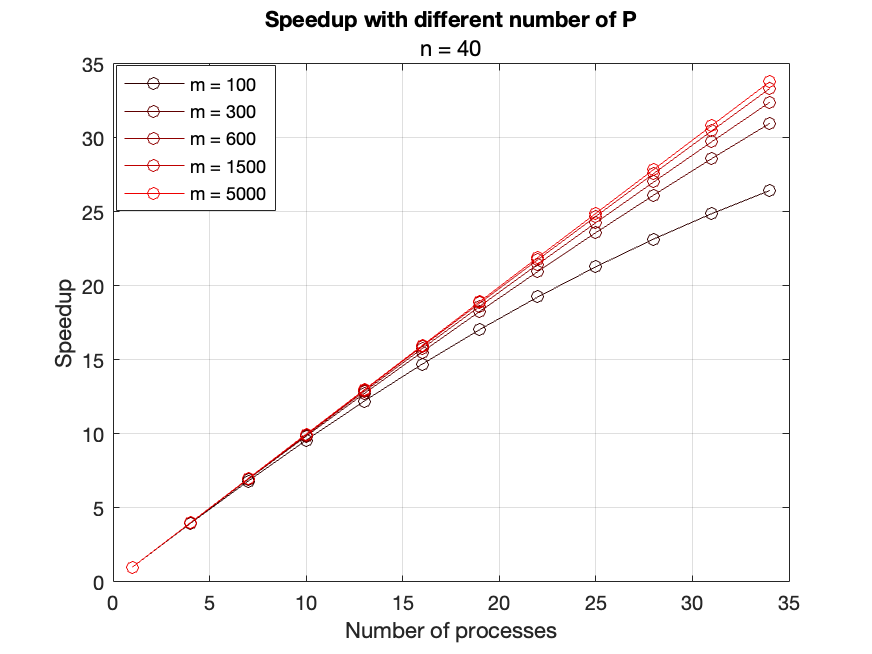

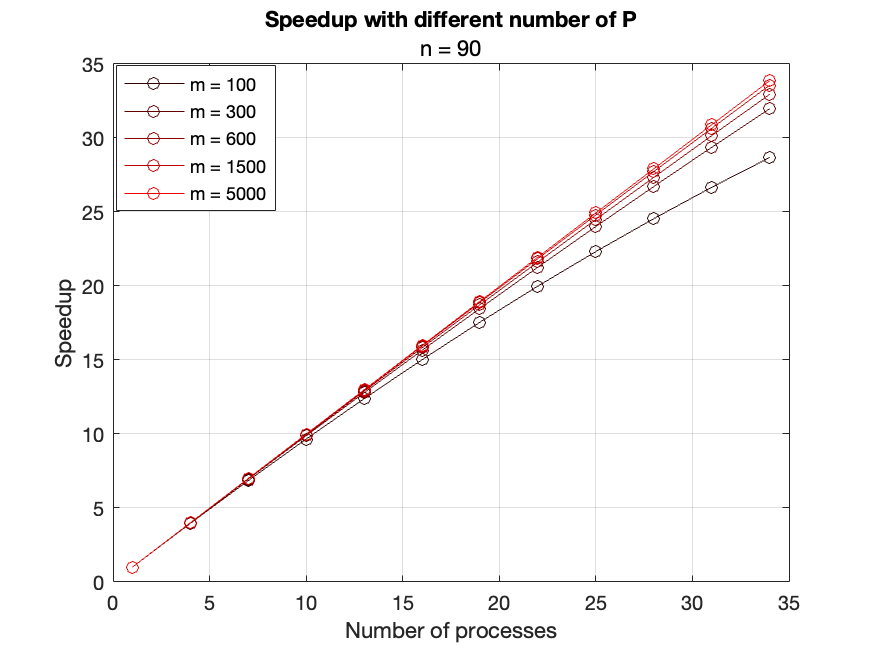

for k=1:5
    for z=1:5
        plot(P,speedup(1,:,z,k),'b-o',Color=[(z*3)/(5*3+1),0,0]);
        hold on
    end
    hold off
    title('Speedup with different number of P');
    subtitle(sprintf('n = %d', n(k)));
    grid on;
    xlabel('Number of processes');
    ylabel('Speedup');
    
    legend("Position",[0.15176,0.67836,0.14447,0.21837]);
    legend('m = 100', 'm = 300' , 'm = 600', 'm = 1500' , 'm = 5000');
    figure()
    

end